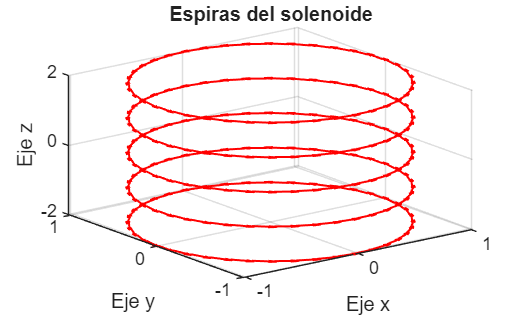

clear;
close all;

% Parámetros del solenoide
nl       = 5;               % Número de espiras
N        = 40;              % Puntos por espira (suavizado)
R        = 1;             % Radio de la espira [m]
sz       = 1;               % Separación entre espiras en z [m]
n_vueltas = 200;            % Número de vueltas del cable
i_cable  = 300;             % Corriente por el cable [A]
I        = n_vueltas * i_cable;  % Corriente total del sistema [A]
mo       = 4*pi*1e-7;       % Permeabilidad magnética del vacío
km       = mo * I / (4*pi); % Constante de Biot-Savart
ds       = 0.1;             % Resolución de malla para visualización

% Parámetros del aro conductor
m          = 40;     % masa del aro [kg]
gamma      = 0.08;   % coeficiente de fricción viscosa
g          = 9.81;   % gravedad [m/s²]
R_espira   = 0.85;    % radio del aro conductor [m]
R_circuito = 0.001;  % resistencia eléctrica del aro [Ohms]
ds_flujo   = 0.02;   % resolución de la malla para flujo

% Espiras del solenoide
[Px,Py,Pz,dPx,dPy,dPz] = espiras(nl, N, R, sz);

% Plot de las espiras
figure('Color','w');
hold on;
quiver3(Px, Py, Pz, dPx, dPy, dPz, 0.5, 'r', 'LineWidth', 1);
grid on; view(3);
title('Espiras del solenoide');
xlabel('Eje x'); ylabel('Eje y'); zlabel('Eje z');
hold off;

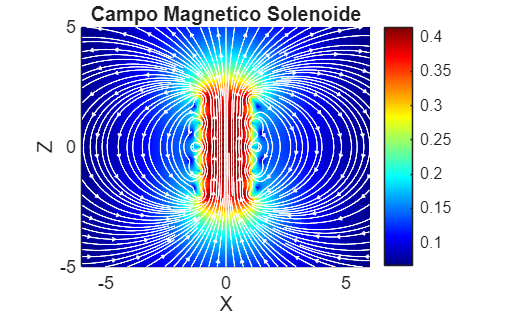


% Campo magnético (malla gruesa para visualización)
[Bx, By, Bz3D, rx, ry, rz] = campoB(ds, km, Px, Py, Pz, dPx, dPy, dPz, 1);
Bmag    = sqrt(Bx.^2 + By.^2 + Bz3D.^2);
Bx_2D   = squeeze(Bx(:, 1, :))';
Bz_2D   = squeeze(Bz3D(:, 1, :))';
Bmag_2D = squeeze(Bmag(:, 1, :))';

% Gráfica 2D del campo
figure('Color', 'w');
hold on;
pcolor(rx, rz, Bmag_2D.^(1/3));
shading interp;
colormap(jet(256)); colorbar;
st = streamslice(rx, rz, Bx_2D, Bz_2D, 3);
set(st, 'Color', 'w', 'LineWidth', 0.8);
axis equal tight;
xlabel('X'); ylabel('Z');
title('Campo Magnetico Solenoide');
xlim([-6 6]); ylim([-5 5]);
hold off;

% Guardar imagen de fondo
exportgraphics(gcf,'campo_magnetico.png','Resolution',300);

clear Bx By Bmag Bx_2D Bz_2D Bmag_2D;

% Eddy - calcular Bz en malla 2D propia
x_malla = -R_espira*1.5 : ds_flujo : R_espira*1.5;
y_malla = x_malla;
z_axis  = -5.2 : ds_flujo : 5.2;

Lx = length(x_malla);
Ly = length(y_malla);
Lz = length(z_axis);

fprintf('Calculando campo Bz en malla 3D para flujo...\n');

Calculando campo Bz en malla 3D para flujo...



Bz_3D = zeros(Lx, Ly, Lz, 'single');
rw = 0.2;  % regularizador (igual que en campoB)

for i = 1:Lx
    for j = 1:Ly
        for k = 1:Lz
            for l = 1:length(Px)
                drx = x_malla(i) - Px(l);
                dry = y_malla(j) - Py(l);
                drz = z_axis(k)  - Pz(l);
                r3  = (drx^2 + dry^2 + drz^2 + rw^2)^1.5;
                Bz_3D(i,j,k) = Bz_3D(i,j,k) + km*(dPx(l)*dry - dPy(l)*drx)/r3;
            end
        end
    end
end

fprintf('Campo calculado.\n');

Campo calculado.


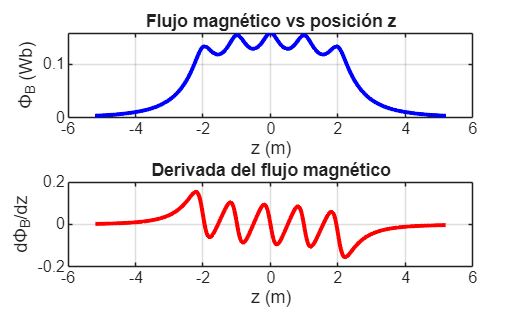


% Flujo magnético en cada z
phiB = zeros(1, Lz);
for k = 1:Lz
    Bz_slice = squeeze(Bz_3D(:, :, k));
    phiB(k)  = flujoB(Bz_slice, x_malla, y_malla, R_espira);
end

% Derivada discreta del flujo
dPhi_dz = diff(phiB) ./ diff(z_axis);
z_mid   = (z_axis(1:end-1) + z_axis(2:end)) / 2;

% Gráfica del flujo y su derivada
figure;
subplot(2,1,1);
plot(z_axis, phiB, 'b', 'LineWidth', 2);
xlabel('z (m)'); ylabel('\Phi_B (Wb)');
title('Flujo magnético vs posición z');
grid on;

subplot(2,1,2);
plot(z_mid, dPhi_dz, 'r', 'LineWidth', 2);
xlabel('z (m)'); ylabel('d\Phi_B/dz');
title('Derivada del flujo magnético');
grid on;

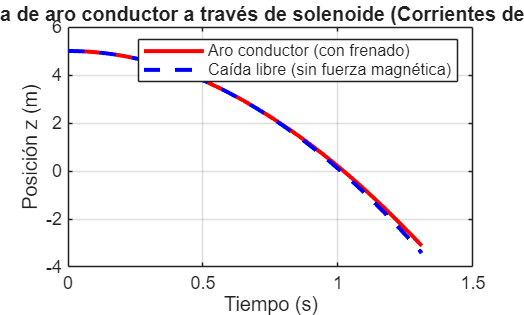


% Condiciones iniciales
dt     = 0.01;
z_fin  = -3.0;  % simular hasta que el aro pase todas las espiras [m]

zm = 5.0;   % posición inicial [m]
vz = 0.0;   % velocidad inicial [m/s]
tt = 0.0;   % tiempo inicial [s]

% Guardar trayectoria
zm_hist = zm;
vz_hist = vz;
tt_hist = tt;

% Simulación con RK4 - hasta z_fin
a_func = @(z, v) a_total_eddy(z, v, dPhi_dz, z_mid, R_circuito, gamma, m);

while zm > z_fin
    [zm, vz] = rk4_step(zm, vz, dt, a_func);
    tt = tt + dt;
    zm_hist(end+1) = zm;
    vz_hist(end+1) = vz;
    tt_hist(end+1) = tt;
end

% Caída libre de referencia
zm_free  = zm_hist(1) - 0.5 * g * tt_hist.^2;
vz_free  = -g * tt_hist;

% Gráfica posición vs tiempo
figure;
plot(tt_hist, zm_hist, 'r-',  'LineWidth', 2); hold on;
plot(tt_hist, zm_free, 'b--', 'LineWidth', 2);
xlabel('Tiempo (s)'); ylabel('Posición z (m)');
title('Caída de aro conductor a través de solenoide (Corrientes de Eddy)');
legend('Aro conductor (con frenado)', 'Caída libre (sin fuerza magnética)');
grid on;
hold off;

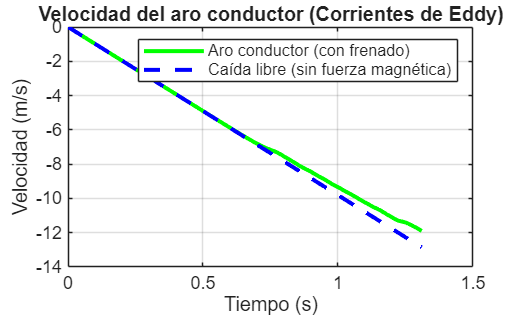


% Gráfica velocidad vs tiempo
figure;
plot(tt_hist, vz_hist, 'g-',  'LineWidth', 2); hold on;
plot(tt_hist, vz_free, 'b--', 'LineWidth', 2);
xlabel('Tiempo (s)'); ylabel('Velocidad (m/s)');
title('Velocidad del aro conductor (Corrientes de Eddy)');
legend('Aro conductor (con frenado)', 'Caída libre (sin fuerza magnética)');
grid on;
hold off;